**Question:**

A Stewart platform is a flat surface connected to a base via six linear actuators; the position and orientation of the surface can be fully controlled within bounds. A common application is to capture a ball thrown at the platform by orienting the surface such that the ball bounces toward the center. Devices typically include cameras that determine the incoming ball’s position and velocity. This leaves the question which we examine in this essay: given the trajectory of a ball travelling towards a planar surface, what is the angle of the plane required to direct the ball’s bounce trajectory toward a desired point?

**Method:**

We present two independent methods for modeling the ball’s trajectory before and after bouncing on the surface. The first is an explicit solution using the parametric equations of motion of a falling body. The position of the ball is denoted as $P(t) = \left(
\matrix{
x(t) \cr
y(t) \cr
z(t)
}
\right)}$, with initial velocity $V_i = \left(
\matrix{
V_{ix} \cr
V_{iy} \cr
V_{iz}
}
\right)}$, and acceleration $A(t) = \left(
\matrix{
0 \cr
0 \cr
-9.80
}
\right)}$. The vector equation for constant linear acceleration is

$P(t) = P(0) + V_i t + \frac{1}{2} A t^2$ . (1)

The bounce occurs where the position vector coincides with the plane, i.e. $P(t_b) \cdot N = 0$ for some value $t_b$, where N is the normal vector of the plane (we assume it passes through the origin). This can be expanded to

$P(t_b) \cdot N = \frac{1}{2} (A \cdot N) t_b^2 + (V_i \cdot N) t_b + P(0) \cdot N = 0$, (2)

and applying the quadratic formula gives

$t_b = \frac{-V_i \cdot N \pm \sqrt{(V_i \cdot N)^2 - 2 (P(0) \cdot N) (A \cdot N)}}{A \cdot N}$ . (3)

Since two values of $t_b$ result, the greater of the two is chosen, so that the ball makes a high arcing trajectory and impacts with the top of the plane. Then the position of the bounce at time $t_b$ is given by equation (1). 

At the point of impact, the ball has velocity $V_f = V_i + At$. The component of the final velocity perpendicular to the plane (parallel with the normal vector) is

$V_{\bot} = \frac{V_f \cdot N}{\|N\|^2} N$. (4)

Then the rebound velocity has the opposite perpendicular component, scaled by the coefficient of restitution (COR):

$V_{rebound} = V_F - (1 + COR) V_{\bot} = V_F - (1 + COR) \frac{V_f \cdot N}{\|N\|^2} N$. (5)

At this point the formulas may be applied again, with $P(0) = P(t_b)$ and $V_i = V_{rebound}$, to determine the position of the next bounce; subsequent bounces are defined recursively.

**Method 2**

We also implement a hybrid numeric solution by integrating over the acceleration with the ordinary differential equation solver, ode45. At each time step, the position increments proportionally to the velocity, and the velocity in the z direction changes with the acceleration. The simulation is stopped by an event function at the point of the bounce, as above, when the dot product of the position vector and the normal vector is equal to zero. Then it is reset with the new velocity after the bounce, according to equation (5) above. This method has the advantage of generating points along the trajectory, which are plotted in Figure 1.

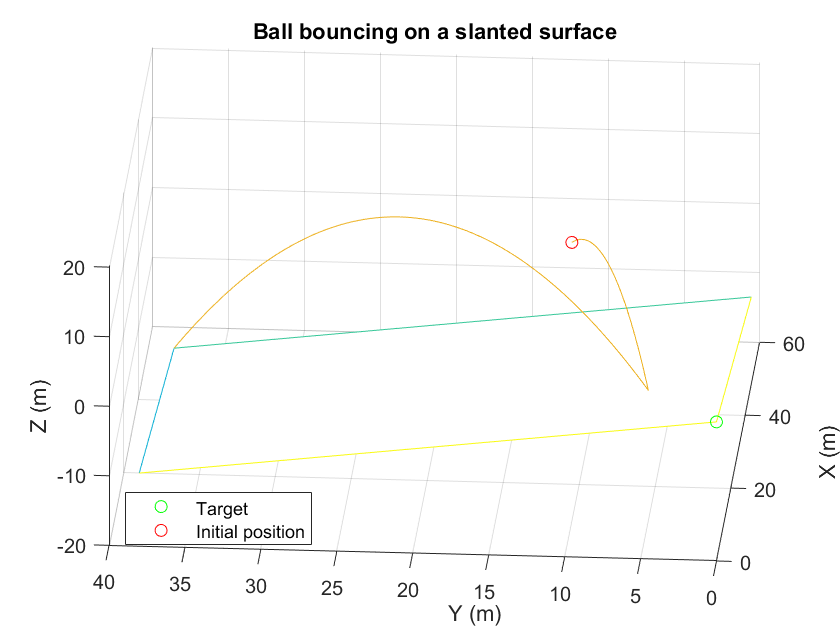

nBounces = 2;
timeout = 10; % seconds
coeff_restitution = 0.95; % unitless
g = 9.80; % m/s^2

p_0 = [10; 10; 20];
v_0 = [2; -2; 2];
normal = [0.15; 0.25; 1]; % this value may be overwritten later
origin = [0; 0; 0];

[T, States, ~, endTimes] = bounceSim(nBounces, timeout, [p_0, v_0], g, coeff_restitution, origin, @(~, ~)(normal), [0, 0], true);
figure()
plot_bounce(States, p_0, normal', T, endTimes);
view([274.1 38.1])
title('Ball bouncing on a slanted surface');

In general, we use the explicit method for determining the bounce position given a set of initial conditions; then we use the MATLAB function fminsearch to optimize the table angle to make the bounce position come as close to the origin as possible, i.e. to mimize $P(t_b) - T_{target}$.

Then the trajectory is simulated using the numeric method, to verify that the resulting table angle directs the ball toward the target, in this case the origin, as shown in Figure 2.

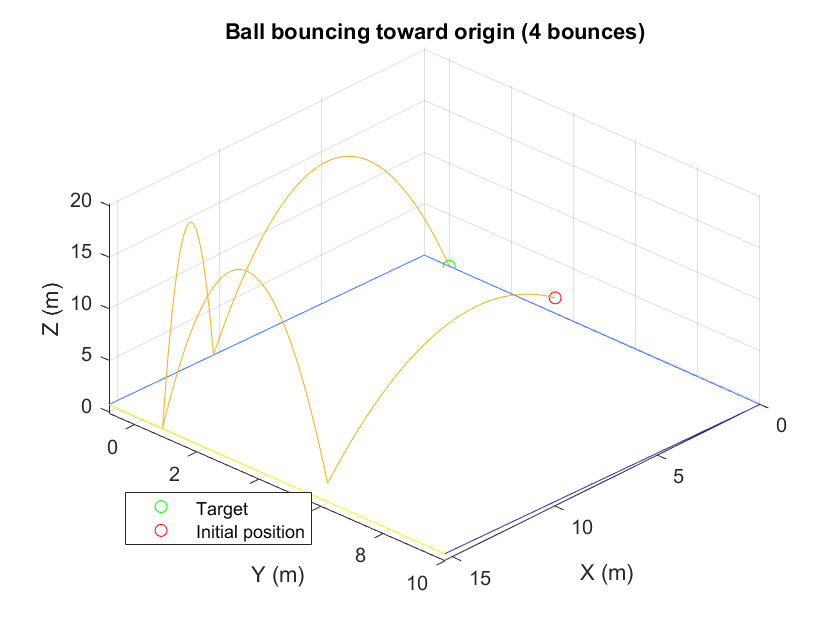

stationary_target = [0, 0];
nBounces = 4;

func_Posf_of_N = @ (N) landing_position(N, nBounces, g, COR, v_0, p_0);
func_XofN = @ (N) (dot(func_Posf_of_N(N), [1 0 0]));
func_YofN = @ (N) (dot(func_Posf_of_N(N), [0 1 0]));

func_DistofN = @ (N) ((func_XofN(N) - stationary_target(1))^2 + (func_YofN(N) - stationary_target(2))^2);

search_options = optimset('MaxFunEvals', 1000);
N = fminsearch(func_DistofN, [0; 0; 1], search_options);
N = N/norm(N);

[T, States, ~, endTimes] = bounceSim(nBounces, timeout, [p_0, v_0], g, coeff_restitution, origin, @(~, ~)(N), stationary_target, true);
figure()

plot_bounce(States, p_0, N', T, endTimes);
view([133.2 45.6]);
title('Ball bouncing toward origin (4 bounces)');